# **Predicting Inferior Temporal (IT) multi unit outputs using Deep Neural Nets and their analyses.**

**Introduction**

Image recognition technology has improved drastically with the advent of deep neural networks (DNN). These neural nets can carry out tasks such as recognizing handwritten digits with an error rate of fraction of a percentage. Now the question arises, how do they compare to ability of brain (primate brain in this case) to recognize objects in images?

Deep neural nets consist of multiple layers to process input images. In a similar way, visual cortex of the primate brain has multiple layers which process visual stimuli incoming from the optic nerve. They are arranged in this order: V1, V2, V3, V4, IT(Inferior Temporal). The IT layer, similar to the final layer of trained DNNs, determine the object in the image.

In this experiment, comparison will be made between 2 of 5 regions in visual cortex of primate brain (V4 & IT) and popular DNN models. Some of the DNN models which will be used for the comparison are:

1) HMO

2) HMAX

3) V1like

4)V2like

5) Krizhevsky et al. 2012

6) Zeiler & Fergus 2013

**1.1) Data acquisition and usage**

While the test subject(primate) was being shown test images, neural output was being recorded from its V4 and IT regions. The V4 region had 128 channels through which neural output was collected, whereas the IT region had 168 channels. So IT representation of one image in the primate brain is a 168 dimension vector. 1960 images were shown in total to the primate, so V4 data matrix is 1960x128, whereas IT data matrix is 1960x168. Here is the link to the data:

[https://s3.amazonaws.com/cadieu-etal-ploscb2014/PLoSCB2014_data_20141216.zip](https://s3.amazonaws.com/cadieu-etal-ploscb2014/PLoSCB2014_data_20141216.zip)

*Only multiunit data will be used here.*

The same set of images were used to make inferences in the DNN models in order to obtain output from their last fully connected layer. Here is the link to the data:

[https://s3.amazonaws.com/cadieu-etal-ploscb2014/PLoSCB2014_models_20150218.zip](https://s3.amazonaws.com/cadieu-etal-ploscb2014/PLoSCB2014_models_20150218.zip)

*All the data here was acquired for Cadieu et al. 2014*

**1.2) Keywords used in functions:**

Certian functions here will take in as arguments keywords representing data type, DNN model and/or region of visual cortex.

**DNN data:**

V1 like=*'V1'*

V2 like=*'V2'*

HMO=*'HMO'*

HMAX=*'HMAX'*

Krizhevsky et al. 2012=*'Kr'*

Zeiler & Fergus 2013=*'Ze'*

**Visual cortex data:**

V4 multiunits=*'V4'*

IT multiunits=*'IT'*

**Data type:**

Visual cortex='*NM*'

DNN='*DNN*'

**2) Reliability**

Using V4 or a DNN feature matrix, each of the 168 channels of IT are predicted using ridge regression. There are ten train/test splits of 70:30, as specified by the meta of the data matrices. Moreover, optimum alpha of ridge regression is determined through three-fold cross-validation on train set. The formula used for ridge regression is:


$$\text{ }\theta ={\left(\mathrm{x'}\ldotp x+\mathrm{G'}\ldotp G\right)}^{-1} \ldotp \mathrm{x'y}$$


where $G=\alpha ∗I_{a\times a}$

where **a **is the number of features of the feature matrix. 

The ridge regression function is *ridge_r.*

After cross-validation, ridge regression is done again on train set using optimum alpha. After p-hat on test set is calculated, it is split into half and Pearson correlation is calcuated between them and their corresponding p values. The mean Pearson correlation between them is calculated to obtain split-half Spearman correlation using this formula:


$$r_{\mathrm{Sp}} =\frac{\left(2∗{\overset{-}{r} }_{\mathrm{Pe}} \right)}{\left(1+{\overset{-}{r} }_{\mathrm{Pe}} \right)}$$


Explained explainable variance is calculated by multiplying Spearman correlation with 100. To represent individual channel, median value is obtained from ten train test splits. This is done for all the channels. To represent a model, the mean explained explainable variance of the 168 channels is taken. The explained variance is the variance of the 168 Spearman correlations times 100.

The lines of code below will calculate such values for HMO, HMAX, V4, Krizhevsky et al. 2012 and Zeiler & Fergus 2013. These results are stored in files with '_model.mat' suffix. The number following model keywords is the number of cores used for parallel computing. **If run on the terminal of openmind:**

squeue slurm HMO 16;
squeue slurm HMAX 16;
squeue slurm Kr 16;
squeue slurm Ze 16;
squeue slurm V4 16;

Otherwise they can be run from Matlab GUI via these function calls:

%Function argument format:
%IT_multi(label_data_path,'model_keyword',no. of cores)
predicted_label_reliability('PLoSCB2014_data_20141216/PLoSCB2014_data_20141216/NeuralData_IT_multiunits.mat','HMO',16);
predicted_label_reliability('PLoSCB2014_data_20141216/PLoSCB2014_data_20141216/NeuralData_IT_multiunits.mat','HMAX',16);
predicted_label_reliability('PLoSCB2014_data_20141216/PLoSCB2014_data_20141216/NeuralData_IT_multiunits.mat','Kr',16);
predicted_label_reliability('PLoSCB2014_data_20141216/PLoSCB2014_data_20141216/NeuralData_IT_multiunits.mat','Ze',16);
predicted_label_reliability('PLoSCB2014_data_20141216/PLoSCB2014_data_20141216/NeuralData_IT_multiunits.mat','V4',16);

Here is a bar chart of the results:

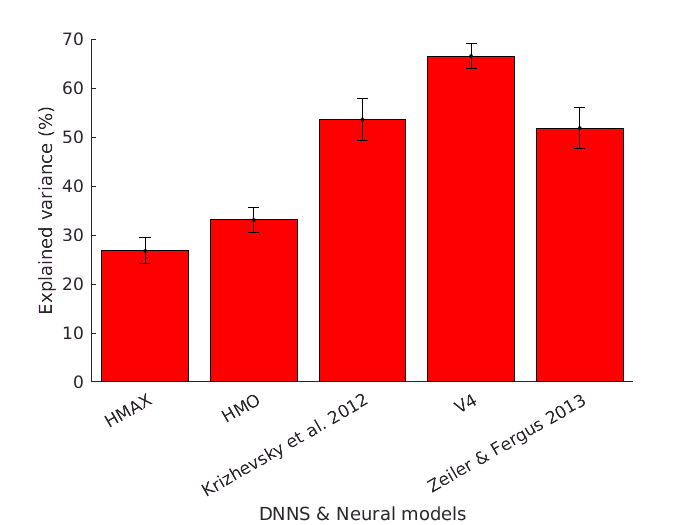

path_suff='_model.mat';
data_arr=categorical({'HMAX','HMO','Kr','V4','Ze'});
data_arr_2=categorical({'HMAX','HMO','Krizhevsky et al. 2012','V4','Zeiler & Fergus 2013'});
exp_var_arr=zeros(1,5);
std_dev=zeros(1,5);
matrix=zeros(5,168);
%For each DNN model:
for i=1:size(exp_var_arr,2)
    m=load([char(data_arr(i)) path_suff]);
    exp_var_arr(i)=m.exp_var;
    std_dev(i)=m.std_dev;
end
figure
hold on
bar(data_arr_2,exp_var_arr,'r')
errorbar(exp_var_arr,std_dev,'.','Color','black')
ylabel('Explained variance (%)')
xlabel('DNNS & Neural models')
ax=gca;
ax.YLim=[0 70];
saveas(gcf,'barplot.png');

The error bars represent explained variance, whereas the barplot represents the explained explainable variance. As can be seen, results of Krizhevsky et al. and Zeiler & Fergus are comparable to that of V4.

Here is a scatter plot of 168 points representing the IT multi unit channels, comparing results of V4 and Zeiler & Fergus.

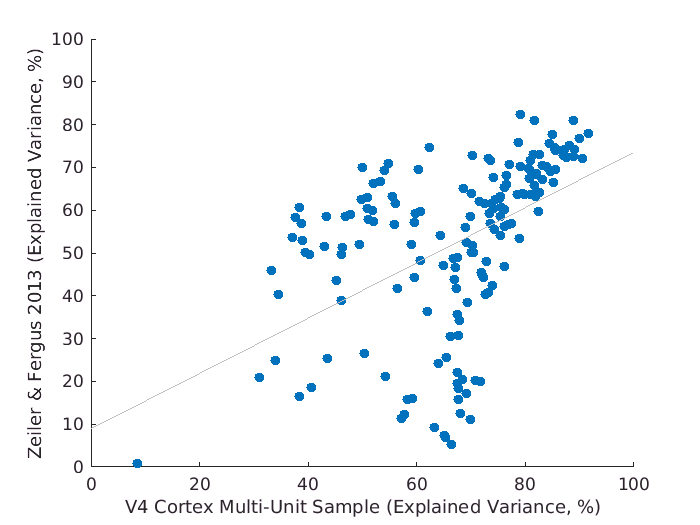

matrix=zeros(5,168);
for i=1:size(exp_var_arr,2)
    m=load([char(data_arr(i)) path_suff]);
    matrix(i,:)=m.arr;
end
figure 
hold on
ze=matrix(end-1,:);
v4=matrix(end,:);
scatter(v4,ze,'filled')
ax=gca;

ax.YLim=[0 100];
ax.XLim=[0 100];
xlabel('V4 Cortex Multi-Unit Sample (Explained Variance, %)')
ylabel('Zeiler & Fergus 2013 (Explained Variance, %)')
lsline
saveas(gcf,'lineplot.png')


r=corrcoef(ze,v4);
disp(['r=' num2str(r(1,2))])

r=0.50379


The Pearson correlation coefficient of the scatter plot is, as can be seen, 0.50379.

**3) RDM calculation**

Seven categories of images were shown to the primate; animals, cars, chairs, faces, fruits, planes, tables. Each category has seven subcategories.

RDM (Representational dissimilarity matrices) will, in this case, display the similarities between IT neural representational vectors of each subcategory. Since there are seven sucategories for each of the seven categories, the RDM matrix calculated here is 49x49. They are calculated using this formula:


$${\text{RDM}\left(\phi \left(x\right)\right)}_{\text{ij}} =1-\frac{\text{cov}\left(\phi \left(x_i \right),\phi \left(x_j \right)\right)}{\sqrt{\text{var}\left(\phi \left(x_i \right)\right)\ldotp \text{var}\left(\phi \left(x_j \right)\right)}}$$


where *i* and *j* are rows of the feature matrix.

Here are the RDMs displayed:

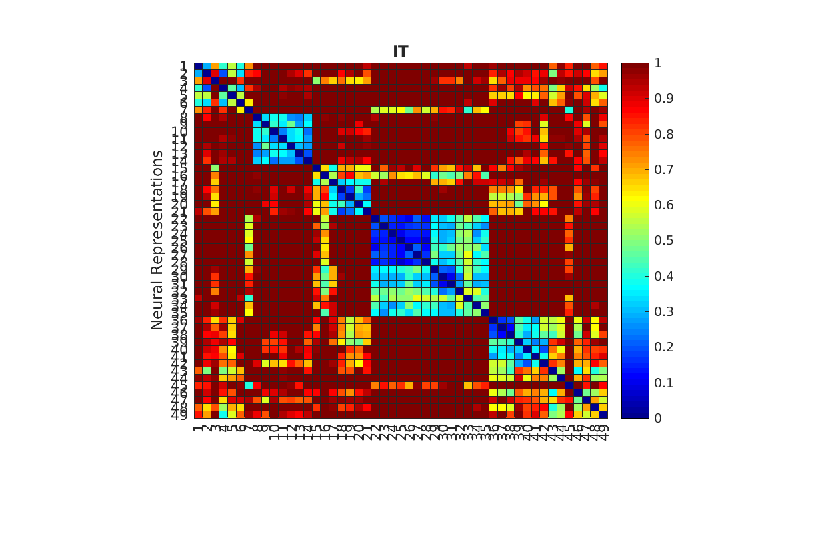

imshow(imread('IT_Neural Representations.png'))

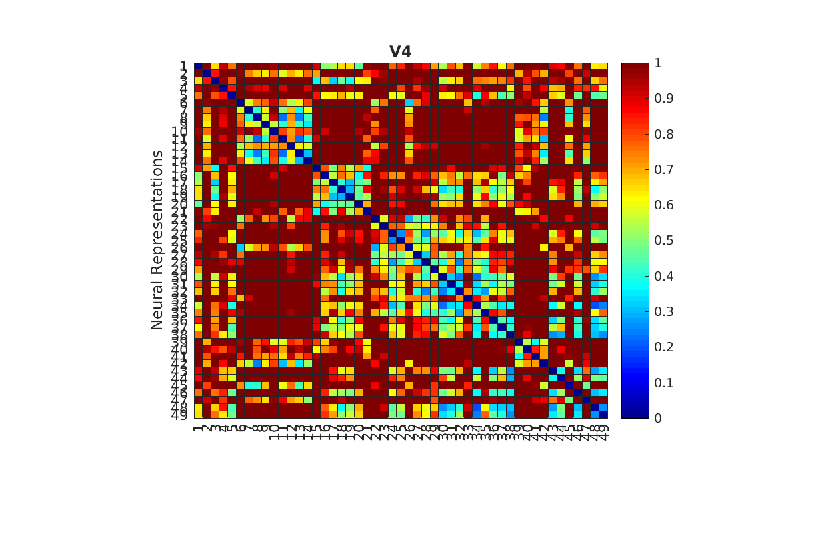

imshow(imread('V4_Neural Representations.png'))

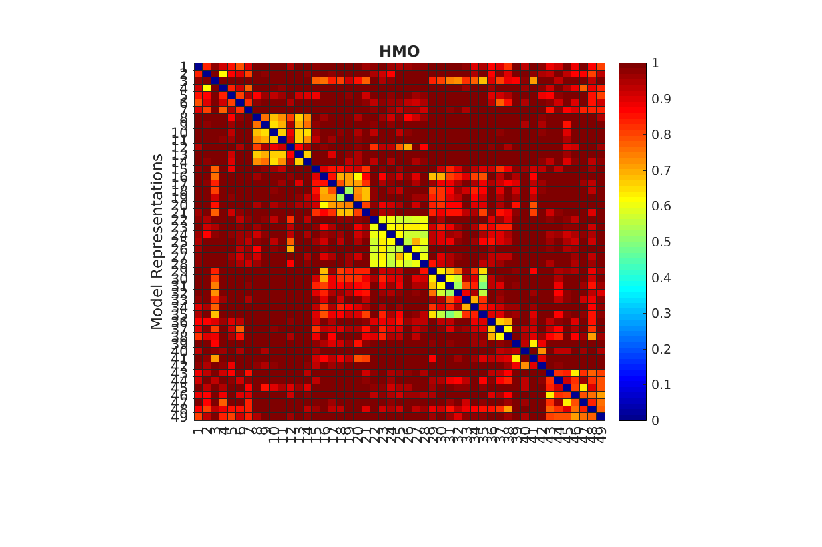

imshow(imread('HMO_Model Representations.png'))

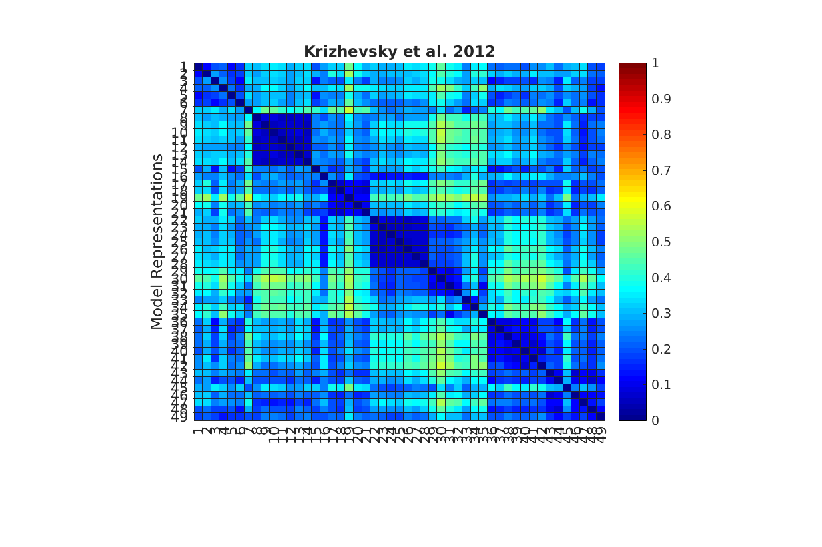

imshow(imread('Krizhevsky et al. 2012_Model Representations.png'))

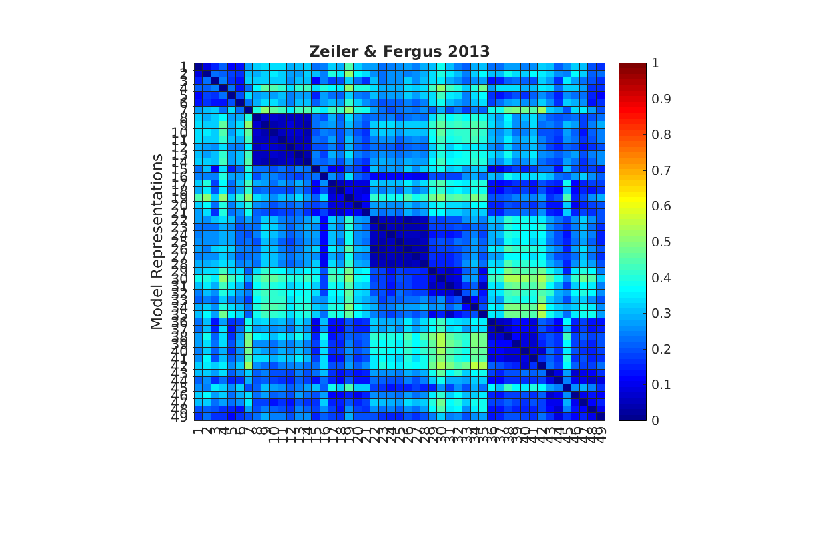

imshow(imread('Zeiler & Fergus 2013_Model Representations.png'))

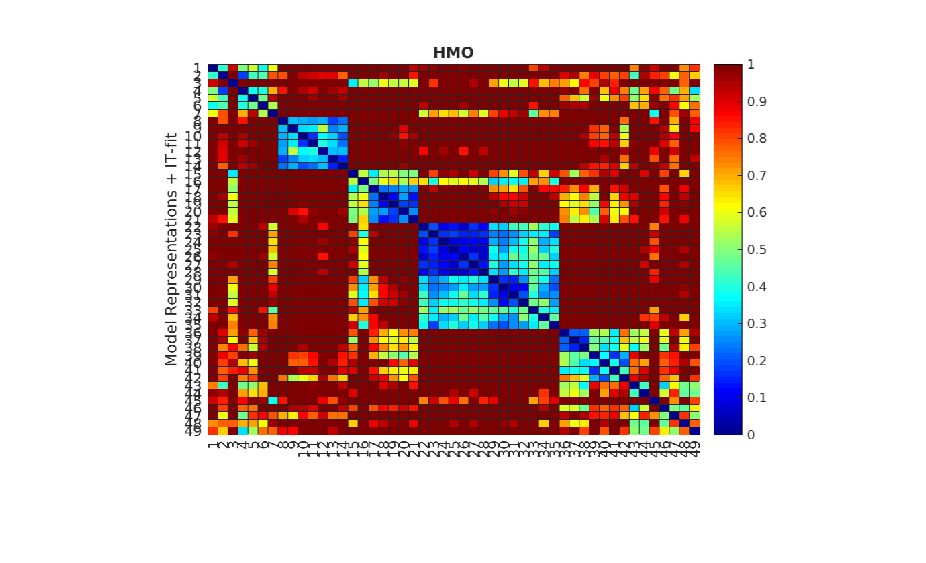

imshow(imread('HMO_Model Representations + IT-fit.png'))

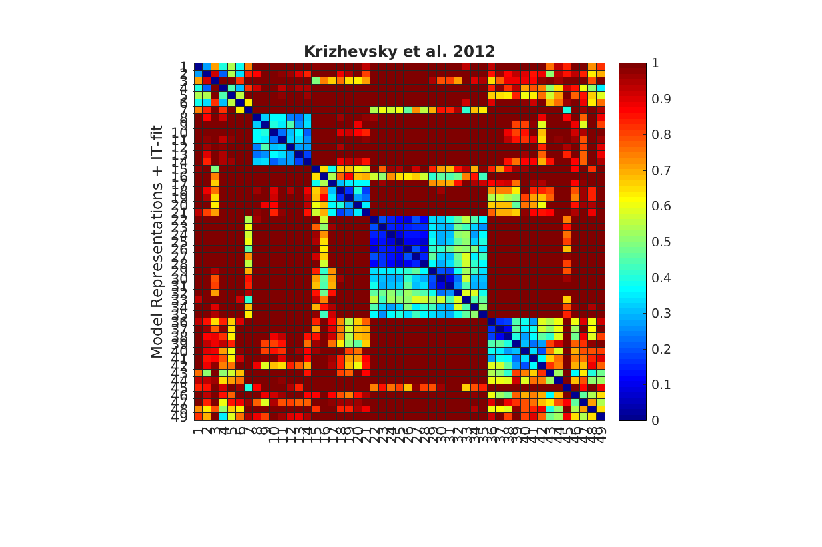

imshow(imread('Krizhevsky et al. 2012_Model Representations + IT-fit.png'))

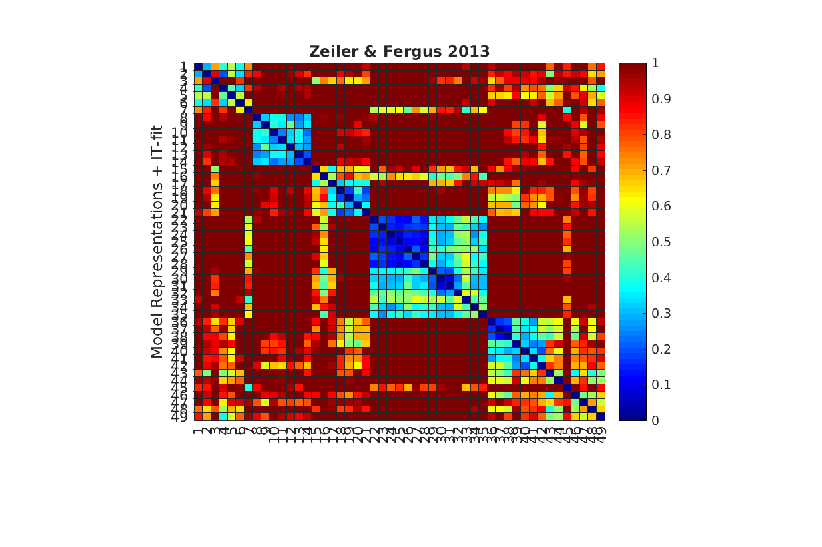

imshow(imread('Zeiler & Fergus 2013_Model Representations + IT-fit.png'))

Lighter color indicates stronger similarity between two subcategories.

The lines below calculate RDM matrices, create heat maps out of them and save them as png images.

RDM_calc('NM','IT');%For IT cortex
RDM_calc('NM','V4');%For V4 cortex

The RDMS calculated with functions above will be saved with  '_Neural Representations.png' suffix.

RDM_calc('DNN','HMO');%For HMO
RDM_calc('DNN','Kr');%For Krizhevsky et al. 2012
RDM_calc('DNN', 'Ze');%For Zeiler & Fergus 2013

The RDMS calculated with functions above will be saved with  '_Model Representations.png' suffix and '_Model Representations + IT-fit.png'.

The RDM_calc function takes in two arguments, data type and neural/model representation name.

Two valid argument values are:

Neural model=*'NM'*

Deep Neural Network=*'DNN'*

To obtain RDMs of IT outputs predicted by HMO, Krizhevsky et al. and Zeiler & Fergus, *IT_predictor *function is used*. *It takes in arguments the same way as RDM_calc does. It predicts IT outputs the same way as *IT_multi *does, but there is only one train/test split of 70:30. 

**4) Obtaining output from DNN's final fully connected layer (DNN code)**

In order to evaluate DNNs, a package called *matconvnet* is used. This is the link to the package download:

[http://www.vlfeat.org/matconvnet/download/matconvnet-1.0-beta24.tar.gz](http://www.vlfeat.org/matconvnet/download/matconvnet-1.0-beta24.tar.gz)

After downloading, unzipping the package and getting into package directory, these lines should be run:

mex -setup;
addpath matlab;
vl_compilenn;

This should be done everytime matlab is started in order to use this package.

These lines of code will generate DNN code, which is a 4096-dimensional output 

of the final fully-connected layer of pretrained AlexNet model. This is the link to download the model:

[http://www.vlfeat.org/matconvnet/models/imagenet-caffe-alex.mat](http://www.vlfeat.org/matconvnet/models/imagenet-caffe-alex.mat)

It should be kept in the same directory as the script below.

net=load('alexnet-caffe');%loading Alexnet
net=vl_simplenn_tidy(net);%Replacing empty values in Alexnet model with zero
fcn_shape=net.layers{end-1}.size(3);% Feature count of final fully connected layer 
img_norm_meta=net.meta.normalization;%AlexNet meta which contains: i) Average image ii) image dimesions used to train model
if ~exist('imdb.mat','file')
    image_database(img_norm_meta.imageSize(1),net.meta.normalization.averageImage);%Creating matrix of all input images
end
data=load('imdb.mat');%Loading input image database
net.layers=net.layers(1:end-2);%Keeping model until last fully connected layer
feat=vl_simplenn(net,data.images.data);%Calculating DNN code of input images
a=squeeze(feat(end).x).';
save('AlexNet2012','a');%Saving DNN code

*imdb.mat *creates a database of input images, which are 227x227x3 center crops of the images. Mean image of pretrained model is subtracted from each image matrix.